x = discretize_load(10,27.25,2001)

x =        1.3386       5180.1
       4.0608       4634.8
       6.7822       4089.5
       9.5026       3544.3
       12.221         2999
       14.937       2453.7
       17.648       1908.5
       20.347       1363.2
       23.011       817.91
       25.433       272.64


moment_error(x,27.25,2001)

Mpoint =    1.3274e+05


Mdist =    1.3283e+05


ans =         93.35


errors = loopP(2001,27.25)

Mpoint =    1.0834e+05


Mdist =    1.3283e+05


Mpoint =    1.0834e+05


Mdist =    1.3283e+05


Mpoint =    1.2153e+05


Mdist =    1.3283e+05


Mpoint =    1.3059e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


Mpoint =    1.3256e+05


Mdist =    1.3283e+05


Mpoint =    1.3158e+05


Mdist =    1.3283e+05


Mpoint =    1.3059e+05


Mdist =    1.3283e+05


Mpoint =    1.3212e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


Mpoint =    1.3281e+05


Mdist =    1.3283e+05


Mpoint =    1.3256e+05


Mdist =    1.3283e+05


Mpoint =    1.3213e+05


Mdist =    1.3283e+05


Mpoint =    1.3241e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


Mpoint =    1.3283e+05


Mdist =    1.3283e+05


Mpoint =    1.3276e+05


Mdist =    1.3283e+05


Mpoint =    1.3256e+05


Mdist =    1.3283e+05


Mpoint =    1.3252e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


Mpoint =    1.3283e+05


Mdist =    1.3283e+05


Mpoint =    1.3281e+05


Mdist =    1.3283e+05


Mpoint =    1.3272e+05


Mdist =    1.3283e+05


Mpoint =    1.3257e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


Mpoint =    1.3282e+05


Mdist =    1.3283e+05


Mpoint =    1.3283e+05


Mdist =    1.3283e+05


Mpoint =    1.3278e+05


Mdist =    1.3283e+05


Mpoint =    1.3269e+05


Mdist =    1.3283e+05


Mpoint =    1.3274e+05


Mdist =    1.3283e+05


errors =         24486        24486        11302         2237        93.35       266.47       1247.1         2237       707.03        93.35       19.578       266.47       702.54       423.57        93.35            0       74.095       266.47       314.01        93.35       5.3338       19.578       112.68       257.52        93.35       13.897       3.2406       48.474       139.08        93.35


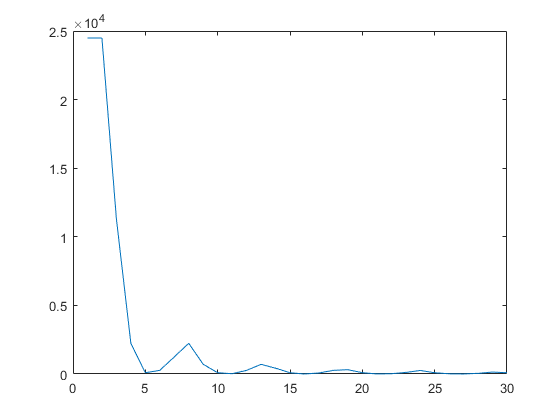

plot((1:30),errors)

format shortG

Functions

function resForce = discretize_load(p,L,w)
    dx = L/p;
    for i = 1:p
        rectangle(i,2) = dx * 2001 * (1 - (dx*i)/L);
        triangle(i,2) = dx * .5 * (2001 - (2001 * (1 - (dx)/L)));
        resForce(i,2) = rectangle(i,2) + triangle(i,2);
        rectangle(i,1) = (dx * 2*i) / 2 - dx/2;
        triangle(i,1) = (dx * 2*i) / 2 - (2*dx)/3;
        resForce(i,1) = (rectangle(i,1) * rectangle(i,2) + triangle(i,1) * triangle(i,2)) / (rectangle(i,2) + triangle(i,2));
    end
end
function error = moment_error(matrix,L,w)
    point = (3*L)/16;
    holderMatrix = matrix(matrix(:,1) >= point,:);
    newMatrix = [holderMatrix(:,1) - point, holderMatrix(:,2)];
    Mpoint = 0;
    for d = 1:size(newMatrix,1)
        Mpoint = Mpoint + (newMatrix(d,1) * newMatrix(d,2));
    end
    Mpoint;
    Mdist = (1/6) * (((-w / L) * point^3) + (3 * w * point^2) - (3 * w * point * L) + (w * L^2));
    error = abs(Mpoint - Mdist);
end
function errorP = loopP(w,L)
    for k = 1:30
        f = discretize_load(k,L,w);
        errorVec(k) = moment_error(f,L,w);
    end
    errorP = errorVec;
end